x = -2.0 : 0.001 : 4.0;
f=@(x)sin(x)-0.5;
plot(x, f(x)); hold on; grid on;

eps = 0.00001; % Точность
y = exp(-x);
x0 = 0.0;
x0A = x0;
N = 100;
for i = 1 : N
    df = (f(x0+0.0000000001)-f(x0))/0.0000000001;
    x1 = x0 - f(x0)/df;
    if abs(x0 - x1) <= eps
        x0
        x1
        i
        break
    end
    x0 = x1;
end

x0 = 0.5236

x1 = 0.5236

i = 4


answer = x1;
for i = 1 : N
    df = (f(x0A+0.0000000001)-f(x0A))/0.0000000001;
    x1 = x0A - f(x0A)/df;
    if abs(x0A - x1) <= eps
        break
    end
    alpha = log(abs(x1-answer))/log(abs(x0A-answer))
    x0A = x1;
end

alpha = 5.7904

alpha = 2.3426

alpha = 2.1410

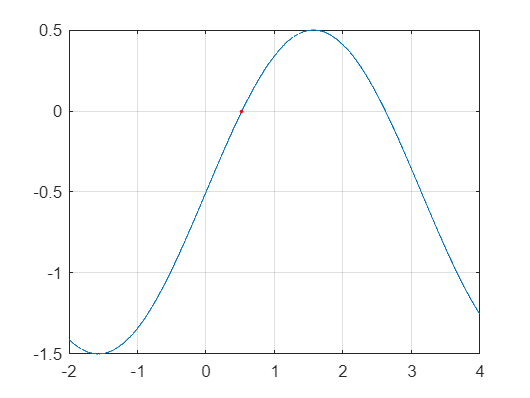


plot(answer, 0, 'r.');